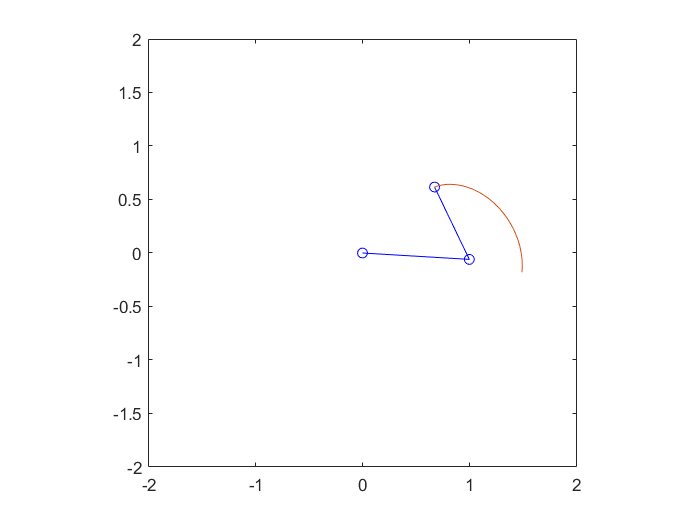

clear all;
close;
clc;

l1=1;
l2=0.75;

t=0:0.1:10;

x=0.5*cos(0.2*t)+1;
y=0.5*sin(0.2*t);

th2 = acos((x.^2 + y.^2 - l1^2 - l2^2)/(2*l1*l2));
th1 = atan(y./x) - acos((x.^2 + y.^2 + l1^2 - l2^2)/(2*l1*sqrt(x.^2 + y.^2)));

for i=1:length(t)
    xA(i)=l1*cos(th1(i));
    yA(i)=l1*sin(th1(i));

    xB(i)=l1*cos(th1(i))+l2*cos(th1(i)+th2(i));
    yB(i)=l1*sin(th1(i))+l2*sin(th1(i)+th2(i));
    
    plot([0 xA(i) xB(i)],[0 yA(i) yB(i)],'b-o');
    axis([-2 2 -2 2]);
    axis square;
    hold on
    plot(xB,yB);
    hold off;
    pause(0.01);
end